# 検出物体の3次元位置取得とロボット座標系への変換

## 初期化

clear; close all force; clc; bdclose all;
useGazebo = true;

## ROSノード登録

if useGazebo
    rosshutdown;
    rosinit('192.168.115.130','NodeHost','192.168.115.1');
end

Shutting down global node /matlab_global_node_75696 with NodeURI http://192.168.115.1:60755/


Initializing global node /matlab_global_node_57173 with NodeURI http://192.168.115.1:49520/


## 3次元点群を取得するためのサブスクライバーを定義

if useGazebo
    ptSub = rossubscriber('/kinect2/sd/points');
    receive(ptSub); % dummy call
end

## 点群を取得

if useGazebo
    ptMsg = receive(ptSub);
    ptMsg.PreserveStructureOnRead = true; % Keep organized point cloud
    clear ptSub;
else
    % あらかじめ保存してある点群を使う場合
    load ptMsg;
end

## 点群から画像データの抽出

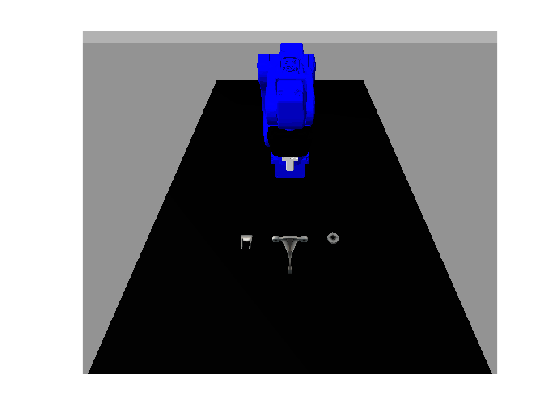

I = readRGB(ptMsg);
figure, imshow(I);

## 点群から深度データの抽出

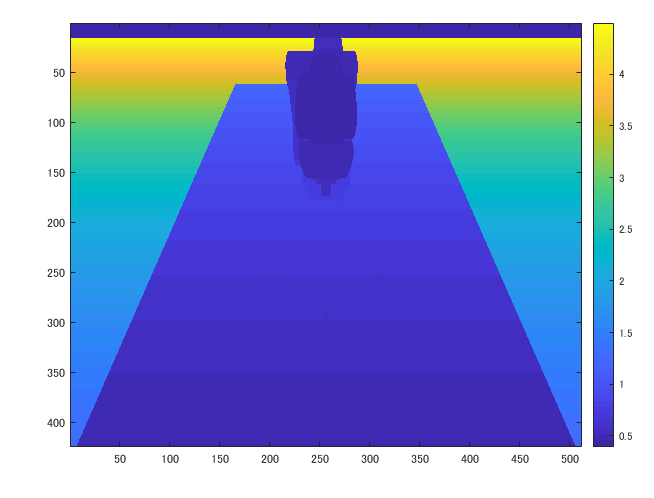

xyz = readXYZ(ptMsg);
figure, imagesc(xyz(:,:,3));
colorbar;truesize;

## 3次元点群として表示

pcfitsphereなどで球体フィッティングも可能

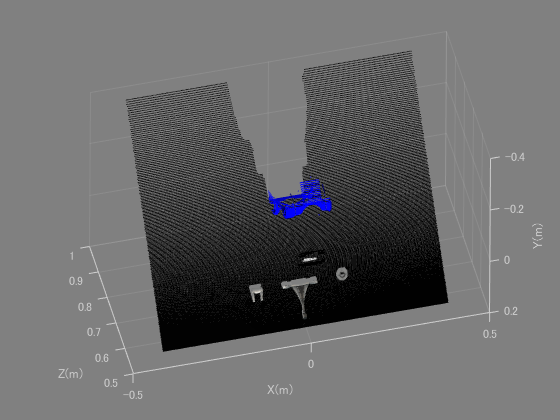

pc = pointCloud(xyz,'Color',I);
hFig = figure;
h = pcshow(pc,'VerticalAxis','Y','VerticalAxisDir','Down');
xlabel('X(m)'),ylabel('Y(m)'),zlabel('Z(m)');
axis([-0.5 0.5 -0.4 0.2 0.5 1]);
hFig.Color = [0.5 0.5 0.5];
h.Color = [0.5 0.5 0.5];

## Kinect座標系からロボット座標系への変換行列取得

変換座標の取得にROS tfを使う

tftree = rostf;
pause(1);
tf = getTransform(tftree,'world','kinect2_rgb_optical_frame');

% あらかじめ保存してあるtf(transform stamped)を使う場合
% load tfSaved

% tfオブジェクトから変換行列を作成
tr = tf.Transform.Translation;
quat = tf.Transform.Rotation;
p = [tr.X tr.Y tr.Z];
q = [quat.W, quat.X, quat.Y, quat.Z];
rotm = quat2rotm(q);
b_T_k = trvec2tform(p)*rotm2tform(rotm)

b_T_k =    -0.0000    0.7833   -0.6216    0.6000
    1.0000    0.0000   -0.0000         0
    0.0000   -0.6216   -0.7833    0.5670
         0         0         0    1.0000


% Simulinkモデルで使うので保存しておく
% save('params','b_T_k');

## MotoMiniをツリー構造ロボットとして表現

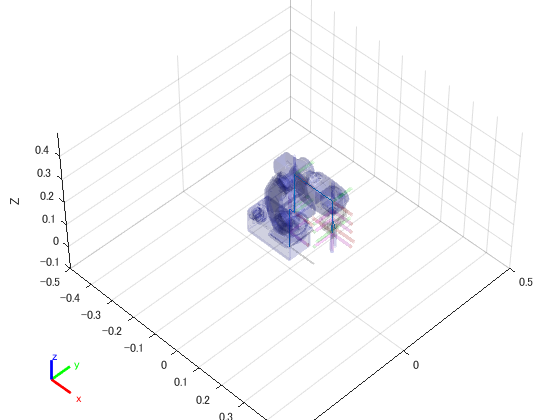

modelName = 'motominiPlanning';
motomini = createMotomini();
restConfig = motomini.homeConfiguration;
hFig2 = figure;
h2 = show(motomini,restConfig,'Frame','on');
hold on;
alpha 0.1;
EELinkName = 'gripper_EE_link';
axis([-0.5 0.5 -0.5 0.5 -0.1 0.5]);
view(45,45)

motominiParams = setMotominiParameters('',motomini);

## 点群の座標変換

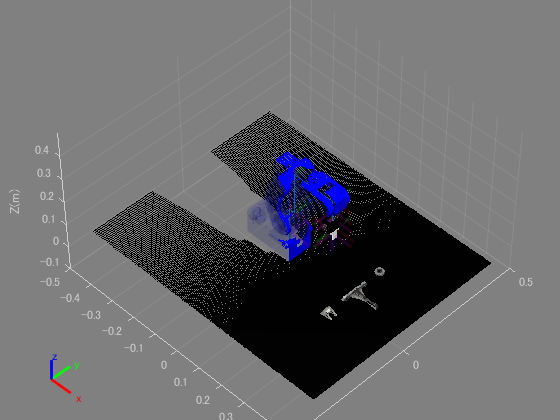

pc_b = pctransform(pc,affine3d(b_T_k'));
set(gcf,'Visible','on')
pcshow(pc_b);
xlabel('X(m)'),ylabel('Y(m)'),zlabel('Z(m)');
axis([-0.5 0.5 -0.5 0.5 -0.1 0.5]);
hFig2.Color = [0.5 0.5 0.5];
h2.Color = [0.5 0.5 0.5];
view(45,45)

## System Objectを使ったYOLO v2による物体検出と位置推定

detector = ObjectDetectorYOLOv2('tform',b_T_k);

## YOLO v2による物体検出の実行

[predictedLabels,bboxes,xyzPoints] = step(detector,I,xyz)

predictedLabels = 3×12 の char 配列
    'arm_part    '
    'disk_part   '
    't_brace_part'

bboxes =    179   235    50    49
   276   233    56    49
   225   245    53    63


xyzPoints =     0.2904   -0.1168    0.0069
    0.2852    0.1062    0.0066
    0.3280   -0.0097   -0.0000


## 結果の可視化

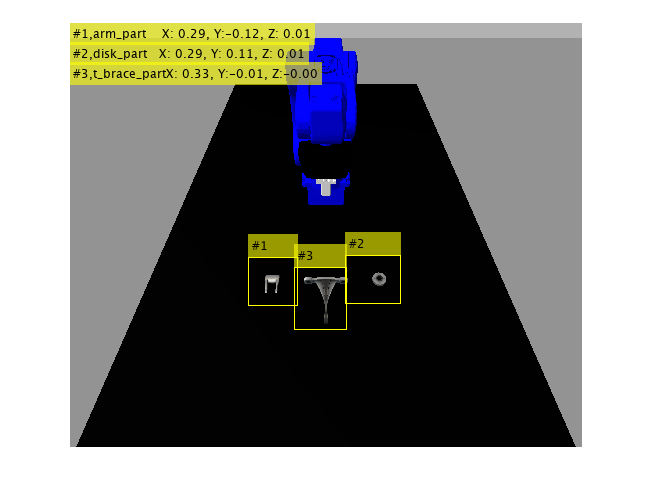

l = size(predictedLabels,1);
Iout = insertObjectAnnotation(I,'rectangle',bboxes,...
    cellstr(num2str((1:l)','#%1.0f')));
Iout = insertText(Iout,[zeros(l,1) (0:l-1)'*20],...
    cellstr([num2str((1:l)','#%1.0f, ') ...
    num2str(predictedLabels,'Label:%s,') ...
    num2str(xyzPoints,'X:% 2.2f, Y:% 2.2f, Z:% 2.2f')]));
figure, imshow(Iout);
truesize;

## 最終姿勢の設定

ピッキングしたい物体の座標位置を取り出し、姿勢を定義

% 最終姿勢
Xf.p =  xyzPoints(1,:)' + [0;0;0.1];  % 1番目のオブジェクト
Xf.ezyx = [pi+pi/2; pi; 0]; % 姿勢は任意に定義

## 最終姿勢の逆運動学を解く

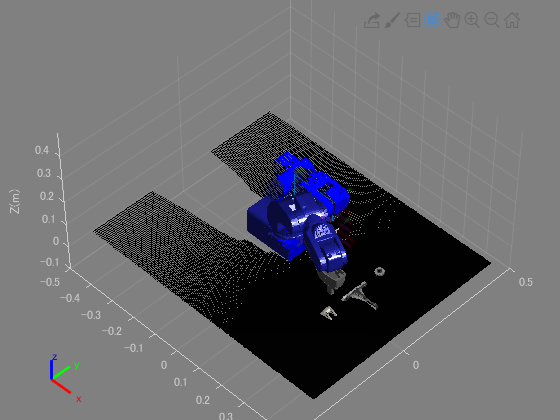

% 関節角計算
[qf, ~] = solveIK(motomini,EELinkName, Xf.p, Xf.ezyx, [restConfig.JointPosition]);
finalConfig = restConfig;
finalConfig = arrayfun(@(x,y) setfield(x, 'JointPosition', y), finalConfig, qf);
figure(hFig2);
set(gcf,'Visible','on');
show(motomini,finalConfig,'PreservePlot',true,'Frames','off');

shg;

## 線形補間で初期軌道を生成

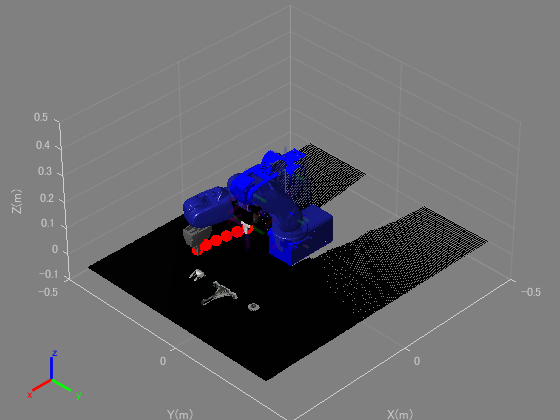

% 実行までの時間
totalTime = 4;
% 障害物
obstacles = [];
% 経由点の数
numPoints = 4;
% 並列計算の有無
useParallel = false;
% 可視化
showMultibodyExplorer = true;

% 線形補間で初期軌道を生成
t0 = 0;
q0 = [restConfig.JointPosition]';
t = linspace(t0,totalTime,numPoints + 2);
Q0 = zeros(motominiParams.numJoints, numPoints + 2);
for i = 1:motominiParams.numJoints
    Q0(i,:) = linspace(q0(i), qf(i),numPoints + 2);
end
Qt = Q0;

% Robotics System Toolboxで軌道を可視化
% 軌道を関節座標系からEEの作業座標系に変換
Xt = zeros(size(Qt,2),3);
config = restConfig;
for k = 1:size(Qt,2)
    config = arrayfun(@(x,y) setfield(x, 'JointPosition', y), config, [Qt(:,k);0;0]');
    Xt(k,:) = tform2trvec(motomini.getTransform(config,'gripper_EE_link'));
end
XYZOr = calcXYZFromSplineMatrix(motomini,EELinkName,numPoints,Q0);
hold on;
hXYZOr = plot3(XYZOr(:,1),XYZOr(:,2),XYZOr(:,3),'-ro','LineWidth',3);
view(135,35)

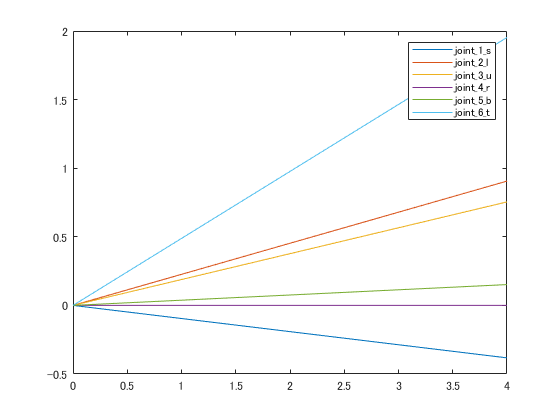

shg;
figure;
plot(t,Qt');
legend(motominiParams.jntNames,'Interpreter',"none");

## Simscape Multibodyで逆動力学シミュレーション(線形補間軌道)

Simscape MultibodyのMechanics Explorer でアニメーション化

% open_system(modelName);
% set_param([modelName '/Draw Trajectory'],'Commented','on');
% set_param(modelName,'SimMechanicsOpenEditorOnUpdate','on');
% MotominiParams.jntMaxLim = motominiParams.jntMaxLim;
% MotominiParams.jntMinLim = motominiParams.jntMinLim;
% sim(modelName);

## 軌道計画を最適化問題として解く

FMINCONを呼んで最適化を解く

時間がかかるので必要に応じて「停止」をクリックして最適化を止める

% doOptim = false;
% [QOpt,Q0,t,Qout,dQout] = planTrajectory(doOptim,q0, qf, totalTime, ...
%     numPoints, obstacles, motominiParams, modelName, useParallel,...
%     showMultibodyExplorer);


## 3次スプライン補間による軌道生成と可視化

%XYZOpt = calcXYZFromSplineMatrix(motomini,EELinkName,numPoints,QOpt);
%figure(hFig2);
%plot3(XYZOpt(:,1),XYZOpt(:,2),XYZOpt(:,3),'-o','LineWidth',3);
%view(45,45);
%shg;

## 生成した軌道のシミュレーション

Show results of optimization in Multibody Explorer

% q0 = Q0(:,1);
% Qt = QOpt;
%set_param(modelName,'SimMechanicsOpenEditorOnUpdate','on');
%sim(modelName);

## ROS経由で関節情報を取得

if useGazebo
    % Gazeboの設定変更のAPIオブジェクトを作成
    gazebo = ExampleHelperGazeboCommunicator();
    
    % 物理エンジンのタイムステップを下げる(=高速化される)
    pauseSim(gazebo);
    phys = readPhysics(gazebo);
    phys.TimeStep = 0.001;
    phys.UpdateRate = 1000;
    setPhysics(gazebo,phys);
    resumeSim(gazebo);
end
if useGazebo
    %% Get state from robot
    armStateSub = rossubscriber('/motomini_controller/state');
    pause(1)
    qAct = armStateSub.LatestMessage.Actual.Positions
    display(armStateSub.LatestMessage.JointNames);
end

## ROS経由で軌道情報を送信し、リーチング姿勢へ

if useGazebo
    %% Create publisher and message to send command to robot
    [armCmdPub,armCmdMsg] = rospublisher('/motomini_controller/command')
    display(armCmdMsg);    % 'trajectory_msgs/JointTrajectory'
    
    %% Create Joint Trajectory Point messages
    % Joint Trajectory Point 1: all joints to zero

qAct = 	1.0e+-4 *

   -0.0000
    0.0006
   -0.6587
   -0.0001
    0.6314
   -0.0001


  6×1 の cell 配列
    {'joint_1_s'}
    {'joint_2_l'}
    {'joint_3_u'}
    {'joint_4_r'}
    {'joint_5_b'}
    {'joint_6_t'}


armCmdPub =   Publisher のプロパティ:

         TopicName: '/motomini_controller/command'
        IsLatching: 1
    NumSubscribers: 0
       MessageType: 'trajectory_msgs/JointTrajectory'

armCmdMsg =   ROS JointTrajectory message with properties:

    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 Header]
     JointNames: {6×1 cell}
         Points: [6×1 JointTrajectoryPoint]
  Use showdetails to show the contents of the message

armCmdMsg =   ROS JointTrajectory message with properties:

    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 Header]
     JointNames: {6×1 cell}
         Points: [6×1 JointTrajectoryPoint]
  Use showdetails to show the contents of the message

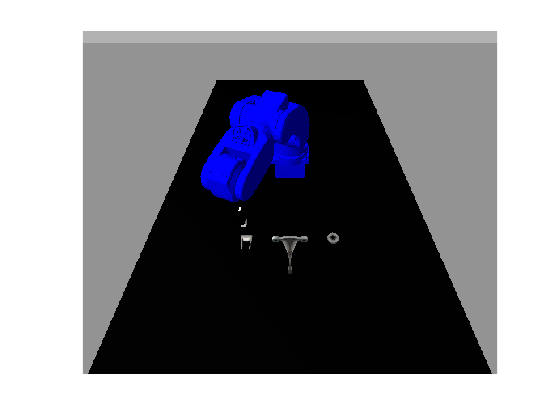

    jntJTPs = arrayfun(@(~) rosmessage(rostype.trajectory_msgs_JointTrajectoryPoint),zeros(1,numPoints+2));
    for k = 1:(numPoints+2)
        jntJTPs(k) = rosmessage(rostype.trajectory_msgs_JointTrajectoryPoint);
        dur1 = rosduration(totalTime/(numPoints+2)*k);
        jntJTPs(k).TimeFromStart = copy(dur1);
        jntJTPs(k).Positions = Qt(:,k);
        jntJTPs(k).Velocities = zeros(motominiParams.numJoints,1);
    end
    %% Configure command message 'trajectory_msgs/JointTrajectory' and send
    armCmdMsg.JointNames = motominiParams.jntNames;
    armCmdMsg.Points = jntJTPs;
    send(armCmdPub, armCmdMsg)
    
    pause(40);
    imSub = rossubscriber('/kinect2/sd/image_color');
    imMsg = receive(imSub);
    I = readImage(imMsg);
    figure, imshow(I);

end

## グリッパーオープン

if useGazebo
    %% Get state from robot
    gripperStateSub = rossubscriber('/gripper_controller/state');
    pause(1)
    qAct = gripperStateSub.LatestMessage.Actual.Positions
    display(gripperStateSub.LatestMessage.JointNames);
    
    [gripperPub,gripperMsg] = rospublisher('/gripper_controller/command');
    gripperMsg.JointNames = gripperStateSub.LatestMessage.JointNames;
    
    jntJTPg = rosmessage(rostype.trajectory_msgs_JointTrajectoryPoint);
    dur1 = robotics.ros.msg.Duration;
    dur1.Sec = 1;
    jntJTPg.TimeFromStart = dur1;
    jntJTPg.Positions = [0.03; 0.03];
    jntJTPg.Velocities = zeros(2,1)

    gripperMsg.Points = [jntJTPg];
    send(gripperPub,gripperMsg);
end

qAct = 	1.0e+-4 *

   -0.0000
    0.1591


  2×1 の cell 配列
    {'gripper_finger_joint_l'}
    {'gripper_finger_joint_r'}


jntJTPg =   ROS JointTrajectoryPoint message with properties:

      MessageType: 'trajectory_msgs/JointTrajectoryPoint'
    TimeFromStart: [1×1 Duration]
        Positions: [2×1 double]
       Velocities: [2×1 double]
    Accelerations: [0×1 double]
           Effort: [0×1 double]
  Use showdetails to show the contents of the message

## ピッキング姿勢へ

ピッキングしたい物体の座標位置を取り出し、姿勢を定義

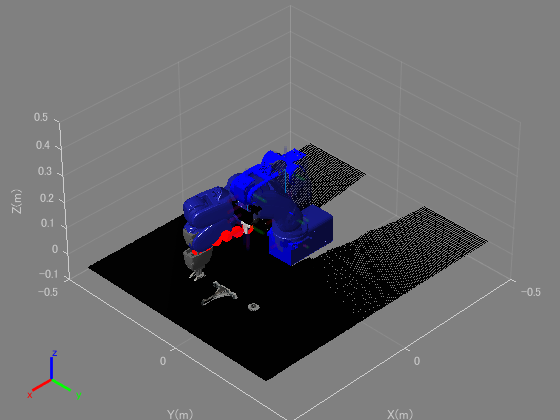

% 最終姿勢
Xf.p =  xyzPoints(1,:)'+[0;0;0.01];  % 1番目のオブジェクト
Xf.ezyx = [pi+pi/2; pi; 0]; % 姿勢は任意に定義
% 関節角計算
[qf, ~] = solveIK(motomini,EELinkName, Xf.p, Xf.ezyx, [restConfig.JointPosition]);
finalConfig = restConfig;
finalConfig = arrayfun(@(x,y) setfield(x, 'JointPosition', y), finalConfig, qf);
figure(hFig2);
set(gcf,'Visible','on');
show(motomini,finalConfig,'PreservePlot',true,'Frames','off');

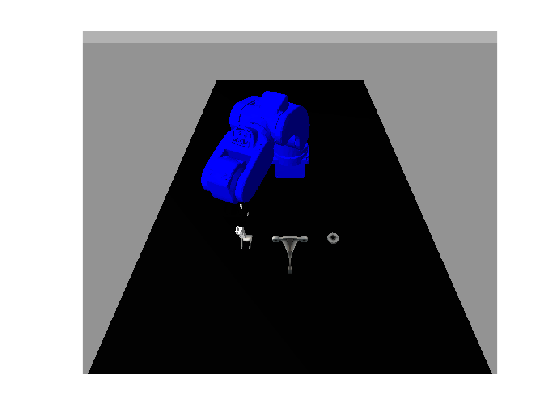


if useGazebo
    jntJTP1 = rosmessage(rostype.trajectory_msgs_JointTrajectoryPoint);
    dur1 = robotics.ros.msg.Duration;
    dur1.Sec = 5;
    jntJTP1.TimeFromStart = dur1;
    jntJTP1.Positions = qf(1:6);
    jntJTP1.Velocities = zeros(motominiParams.numJoints,1);
    armCmdMsg.JointNames = motominiParams.jntNames;
    armCmdMsg.Points = [jntJTP1];
    send(armCmdPub, armCmdMsg)
    pause(5);
    imMsg = receive(imSub);
    I = readImage(imMsg);
    figure, imshow(I);
end

## グリッパークローズ & リーチングポイントに戻る

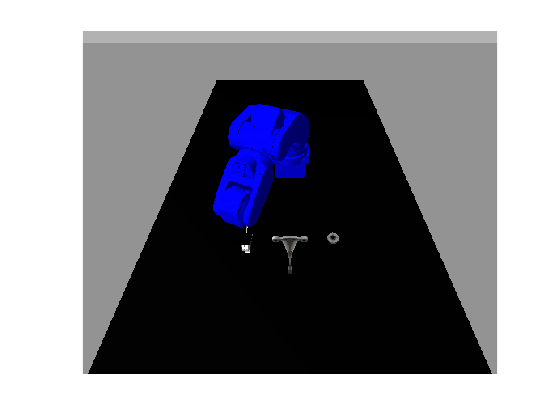

if useGazebo
    % グリッパークローズ
    gripperMsg.Points.Positions = [0, 0];
    send(gripperPub,gripperMsg);
    pause(5);
    imMsg = receive(imSub);
    I = readImage(imMsg);
    figure, imshow(I);
end

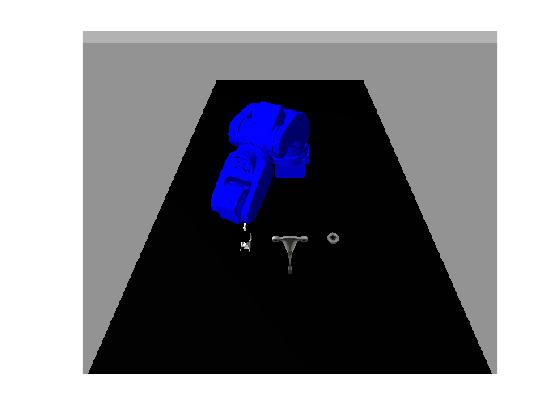

   % リーチングポイントへ戻る
    armCmdMsg.Points = jntJTPs(end);
    send(armCmdPub, armCmdMsg)
    pause(5);
    imMsg = receive(imSub);
    I = readImage(imMsg);
    figure, imshow(I);

Copyright 2019 The MathWorks, Inc.